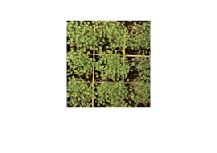

addpath('pictures')



imdata = imread('cc3-t4.png');
og = imdata;

figure 
imshow(imdata)

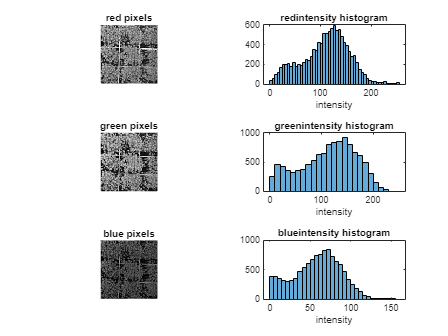


names = {'red','green','blue'};
R = imdata(:,:,1);
G = imdata(:,:,2);
B = imdata(:,:,3);

figure
tiledlayout(3,2)
for k=1:3
    % intensity gray scale of plants and soil
    nexttile 
    imshow(imdata(:,:,k))
    title([char(names{k}), ' pixels'])

    % sorted histogram
    nexttile
    histogram(imdata(:,:,k))
        xlabel('intensity')

    title([char(names{k}), 'intensity histogram'])
end

For the green pixels, the histogram exhibits a staircase-like change at 50.  So, we use 50 as the cutoff darkness.  If a pixel is darker than 50, then we consider it soil.  Similarly, 

Now we build a mask.  Find pixels that are larger than a predetermined value; which correspond to covered pixel or not.

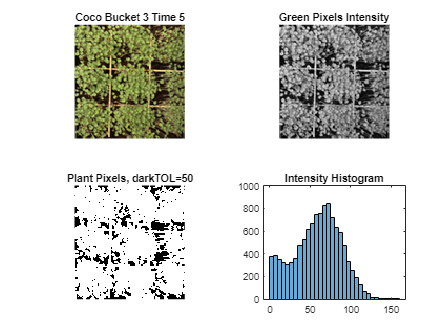

darkTOL = 50;

imdata = imread('cc3-t4.png');
og = imdata;

[coverargepercentage, coveredpixels] = image2coverpercent(og(:,:,2), darkTOL);

figure
    tiledlayout(2,2)
    nexttile 
    imshow(og)
        title('Coco Bucket 3 Time 5')

    nexttile 
    imshow(og(:,:,2))
    title(['Green Pixels Intensity'])

nexttile
imshow(coveredpixels)
title(['Plant Pixels, darkTOL=', num2str(darkTOL)])

nexttile
    histogram(og(:,:,k))
    title('Intensity Histogram')

%% Coco Data

## Coco Data

We now examine 

numbucket = 5;
numtimesteps = 5;
CocoData = zeros(numbucket, numtimesteps);



    
    
    for timestep=1:numtimesteps


        for bucket_index = 1:numbucket
            imagename = ['cc', num2str(bucket_index),'-t',num2str(timestep-1),'.png'];
            imdata = imread(imagename);
            G = imdata(:,:,2);
            darkTOL = 50;
        
    
            [coverargepercentage, coveredpixels] = image2coverpercent(G, darkTOL);
    
            CocoData(bucket_index,timestep) = coverargepercentage;
    
            % figure
            % 
            % tiledlayout(1,2)
            % 
            % nexttile
            % imshow(G);
            % title(['bucket=',num2str(bucket_index),' timestep=',num2str(timestep)])
            % 
            % nexttile 
            % imshow(coveredpixels)
    
        end
    end
    %

    
    

    writematrix(CocoData,'CocoData.csv')


    display(CocoData)

CocoData =      9.538034780753227e-02     8.831342570473005e-01     5.028248587570622e-01     6.982601172738633e-01     8.506419774652808e-01
     7.997835497835498e-02     9.092621664050236e-01     4.015037593984963e-01     7.053391053391054e-01     8.651813018785496e-01
     8.775510204081632e-02     9.059131344845630e-01     4.991269841269841e-01     5.805825242718446e-01     8.397707231040564e-01
     7.367870225013082e-02     8.319047619047619e-01     5.487179487179488e-01     7.414078674948240e-01     8.483643892339544e-01
     9.242424242424242e-02     6.412698412698413e-01     4.022515527950311e-01     7.817687074829932e-01     9.255183413078150e-01


D

## Soil Data

Could account for sticks.

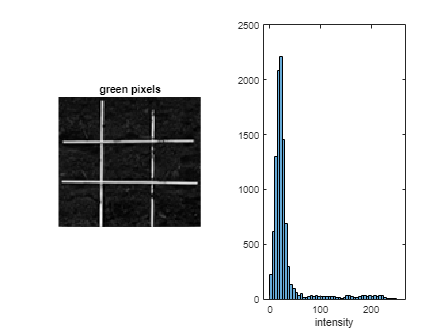

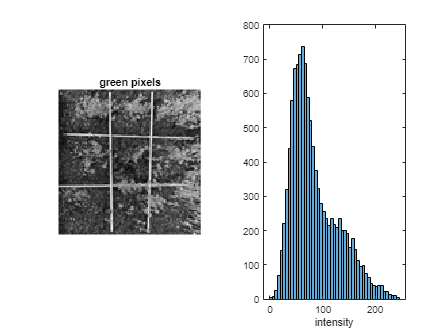

bucket_index=2;
for timestep = [1,4]
    

imagename = ['soil', num2str(bucket_index),'-t',num2str(timestep-1),'.png'];

imdata = imread(imagename);


R = imdata(:,:,1);
G = imdata(:,:,2);
B = imdata(:,:,3);



figure
tiledlayout(1,2)
k=2;

    % intensity gray scale of plants and soil
    nexttile 
    imshow(imdata(:,:,k))
    title([char(names{k}), ' pixels'])

    % sorted histogram
    nexttile
    histogram(imdata(:,:,k))
        xlabel('intensity')
end


    % title([char(names{k}), 'intensity histogram'])

First picture is intensity of sticks.  These pixels which will be counted as plants, creating error.

Second picture helps us pick darkTol.  pick 125, avg of 100 and 150.

    numbucket = 5;
numtimesteps = 5;
SoilData = zeros(numbucket, numtimesteps);



    darkTOL = 125;
    
    for timestep=1:numtimesteps


        for bucket_index = 1:numbucket
            imagename = ['soil', num2str(bucket_index),'-t',num2str(timestep-1),'.png'];
            imdata = imread(imagename);
            G = imdata(:,:,2);
            
        
    
            [coverargepercentage, coveredpixels] = image2coverpercent(G, darkTOL);
    
            SoilData(bucket_index,timestep) = coverargepercentage;
    
            % figure
            % 
            % tiledlayout(1,2)
            % 
            % nexttile
            % imshow(G);
            % title(['bucket=',num2str(bucket_index),' timestep=',num2str(timestep)])
            % 
            % nexttile 
            % imshow(coveredpixels)
    
        end
    end
    %

    writematrix(SoilData,'SoilData.csv')


    display(SoilData)

SoilData =      6.749131944444445e-02     9.875283446712019e-02     6.615171321053674e-02     1.004665379665380e-01     1.113281250000000e-01
     5.406746031746032e-02     1.022501308215594e-01     3.895238095238095e-02     1.994659546061415e-01     2.863095238095238e-01
     6.222838650023116e-02     1.046637211585665e-01     3.609977324263038e-02     9.151927437641723e-02     1.080622347949081e-01
     6.766439909297052e-02     1.276190476190476e-01     4.514285714285714e-02     8.135291499777481e-02     7.165109034267912e-02
     6.040992448759439e-02     1.064004096262161e-01     6.619047619047619e-02     7.472527472527472e-02     5.989199803632794e-02


This text is a little bit bigger than it should be.  I think dominant error is pixels damaged by sticks, which isn't too many.

## Recycled Paper

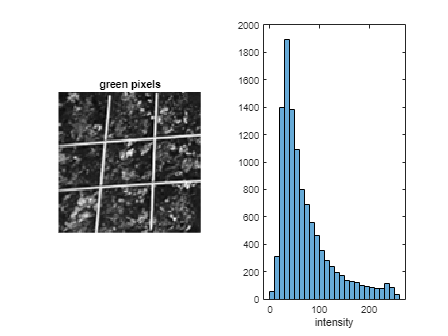

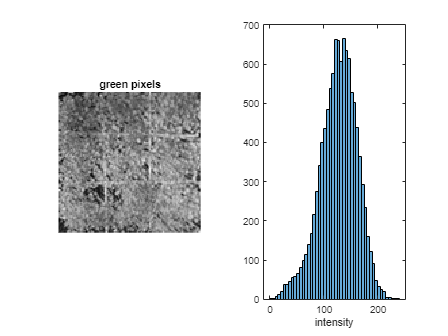

    bucket_index=5;
for timestep = [1,4]
    

imagename = ['paper', num2str(bucket_index),'-t',num2str(timestep-1),'.png'];

imdata = imread(imagename);


R = imdata(:,:,1);
G = imdata(:,:,2);
B = imdata(:,:,3);



figure
tiledlayout(1,2)

k=2;
    % intensity gray scale of plants and soil
    nexttile 
    imshow(imdata(:,:,k))
    title([char(names{k}), ' pixels'])

    % sorted histogram
    nexttile
    histogram(imdata(:,:,k))
        xlabel('intensity')
end

It's hard to tell.  We just settle for Coco's choice of darkTol = 50.

    numbucket = 5;
numtimesteps = 5;
PaperData = zeros(numbucket, numtimesteps);



    darkTOL = 50;
    
    for timestep=1:numtimesteps


        for bucket_index = 1:numbucket
            imagename = ['soil', num2str(bucket_index),'-t',num2str(timestep-1),'.png'];
            imdata = imread(imagename);
            G = imdata(:,:,2);
            
        
    
            [coverargepercentage, coveredpixels] = image2coverpercent(G, darkTOL);
    
            PaperData(bucket_index,timestep) = coverargepercentage;
    
            % figure
            % 
            % tiledlayout(1,2)
            % 
            % nexttile
            % imshow(G);
            % title(['bucket=',num2str(bucket_index),' timestep=',num2str(timestep)])
            % 
            % nexttile 
            % imshow(coveredpixels)
    
        end
    end
    %

    writematrix(PaperData,'PaperData.csv')

    display(PaperData)

PaperData =      1.600477430555556e-01     4.048752834467120e-01     5.363438304614775e-01     8.453989703989704e-01     8.142361111111112e-01
     9.642857142857143e-02     5.448456305599163e-01     3.600952380952381e-01     7.791722296395194e-01     7.828373015873016e-01
     1.095700416088766e-01     4.783505154639175e-01     2.277551020408163e-01     8.430839002267574e-01     7.600188590287600e-01
     1.092970521541950e-01     4.575238095238095e-01     3.306666666666667e-01     8.679127725856698e-01     6.518024032042724e-01
     8.754460210770891e-02     4.187403993855607e-01     5.058095238095238e-01     6.348901098901099e-01     5.191948944526265e-01


This data is definitely larger than it should be, due to paper being high intensity.

## Rock Wool

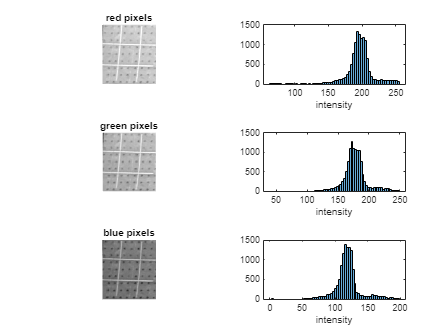

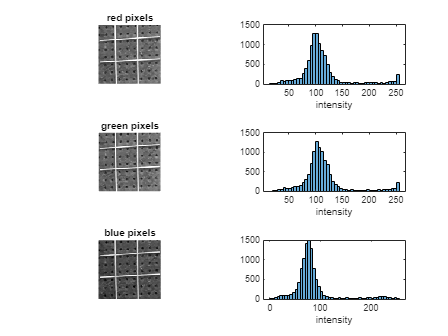

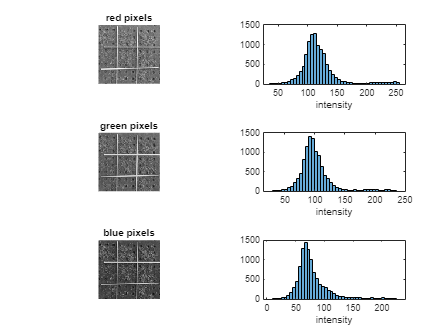

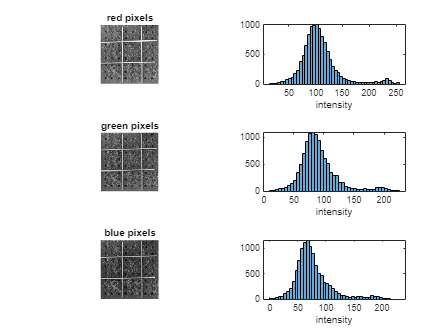

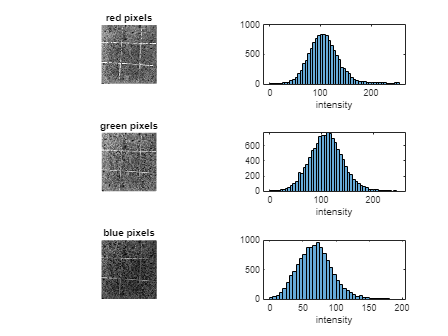

    bucket_index=5;
for timestep = [1:5]
    

imagename = ['rw', num2str(bucket_index),'-t',num2str(timestep-1),'.png'];

imdata = imread(imagename);


R = imdata(:,:,1);
G = imdata(:,:,2);
B = imdata(:,:,3);



figure

tiledlayout(3,2)
            title(['timestep=',num2str(timestep)])

    for k=1:3
    
        % intensity gray scale of plants and soil
        nexttile 
        imshow(imdata(:,:,k))
        title([char(names{k}), ' pixels'])
    
        % sorted histogram
        nexttile
        histogram(imdata(:,:,k))
            xlabel('intensity')
    end 
end

To make sense of this, handle time step by time step.

- Nothing grown. leave as 0%

- By blue, spike at 100.  set darkTol=100

numbucket = 5;
numtimesteps = 5;
RockwoodData = zeros(numbucket, numtimesteps);

% first time step is zero.  leave it alone

% second time step
darkTol = 100;
timestep=2;

for timestep=2:5
    
    for bucket_index = 1:numbucket
        imagename = ['paper', num2str(bucket_index),'-t',num2str(timestep-1),'.png'];
        imdata = imread(imagename);
        G = imdata(:,:,3);
    
    
    
        [coverargepercentage, coveredpixels] = image2coverpercent(G, darkTOL);
    
        RockwoodData(bucket_index,timestep) = coverargepercentage;
    
        % figure
        %
        % tiledlayout(1,2)
        %
        % nexttile
        % imshow(G);
        % title(['bucket=',num2str(bucket_index),' timestep=',num2str(timestep)])
        %
        % nexttile
        % imshow(coveredpixels)
    
    end
end

writematrix(RockwoodData,'RockwoodData.csv')
display(RockwoodData)

RockwoodData =                          0     7.099206349206350e-01     5.736413984077535e-01     7.769764216366158e-01     9.042105263157895e-01
                         0     7.118340405469118e-01     4.226757369614512e-01     8.437355524734166e-01     9.169642857142857e-01
                         0     5.457044673539518e-01     2.921867776236708e-01     5.136740934906072e-01     3.151360544217687e-01
                         0     6.597001763668431e-01     4.933504933504934e-01     7.204433497536946e-01     7.895150720838794e-01
                         0     7.212301587301587e-01     4.556297285269248e-01     8.713369963369964e-01     8.409340659340659e-01


function [coverargepercentage, coveredpixels] = image2coverpercent(img, darkTOL)

%{
Input: in R^(m x n).  not equipped to handle RGB m x n x 3.
darkTOL, the intensity cutoff between soil and plant

Output: % of pixels covered by a plant
coveredpixels R^(m x n) binary, 1=plant, 0 = soil

%}

% darkTOL = 50;

% G = imdata(:,:,2);

G = img;

soil_indices = find(G<darkTOL);

coveredpixels = ones(size(G));
coveredpixels(soil_indices) = 0;



coverargepercentage = sum(sum(coveredpixels))./prod(size(G));

end 
% Build a mask 
